We are glad you are using our code. We will be happy to receive your feedback and help you if needed. If necessary, please contact us at szaksz@mm.bme.hu or at habib@mm.bme.hu. This code is provided freely for scientific purposes, and while not mandatory, we would greatly appreciate if users could acknowledge its use by citing our paper: Szaksz, B., Stepan, G., & Habib, G. (2024). Dynamical integrity estimation in time delayed systems: a rapid iterative algorithm. Journal of Sound and Vibration, 571, 118045.

This is an example code to show, how the algorithm can estimate the local integrity measure (LIM) of a 1DoF machining problem. A parametric analysis is carried out, where the LIM is calculated for different initial functions varying the dimensionless chip width p. 

clear
close all
% clc
set(0,'defaulttextinterpreter','latex')
set(0, 'DefaultLegendInterpreter', 'latex')
set(groot, 'DefaultAxesTickLabelInterpreter', 'latex')

Parameter values for the system and for the computation


% parameter values
zeta1 = 0.05;       % damping ratio
rho1 = 6109.6;      % experimental constant
rho2 = -54141.6;    % experimental constant
rho3 = 203769;      % experimental constant
h0 = .07;           % depth of cut 
eta2 = h0*(rho2+3*rho3*h0)/(rho1+2*rho2*h0+3*rho3*h0^2);    % second order nonlinearity
eta3 = h0^2*rho3/(rho1+2*rho2*h0+3*rho3*h0^2);    % third order nonlinearity
Omd = 0.6987;       % dimensionless spindle speed
tau = 2*pi/Omd;     % delay
Np = 20;    % number of points for the parametric analysis. 
% For 20 points it may take around 1 minute
pvec = linspace(0.13,0.164,Np); % chip width

% time discretization within the semi-discretization
r = 30;      % sampling delay number
dt = tau/(r+1/2);  % time step

% construction of the structure of parameters
par = struct('r',r,'dt',dt,'tau',tau); % these parameters are needed for 
par.zeta1 = zeta1;
par.eta2 = eta2;
par.eta3 = eta3;


% equilibrium point
xe=[0,0];

% variable of the phase space to be plot (unnecessary for this system,
% since it has only 1 DoF)
var1=1;
var2=2;

% number of step of the iteration
number_of_steps=50;

% maximal final time of each simulation
tfinal = 5000;

% space boundary
spaceboundary=[-20,-20,20,20];   % space within the simulations are run i.e.: ([-q1,-dq1,q1,dq1])

% discretization of the phase space in each direction
discr=501;

% figure number
numfig = 103;

Computation of the Local Integrity Measure (LIM) of the system using different initial functions.

% computation of the LIM
for ip = 1 : length(pvec)    
    disp([num2str(ip) '/' num2str(length(pvec))])
    par.p = pvec(ip);
    [par,weight,x1_q,x2_q] = dyn_machining1DoF(par);  % the dynamics of the system
    
    % computation of the LIM. Initial conditions selected as constant (init_type=0)
    [R_final0(ip),OutL,OutH]=compute_LIM_D_FP_HIC(xe,par,'weight',weight,'tfinal',tfinal,...
            'var1',1,'var2',2,'plot_results',0,'plot_results_final',0,'automatic',1,'number_of_steps',number_of_steps,'spaceboundary',spaceboundary,'discr',discr,'rep_fix_point',100,'rep_periodic',50,'num_of_cell_around_equilibrium',3,...
            'ind_check_conv',[1,2,3,4,5,6,7,8,9],'ind_check',[1,2,3,4,5,6,7,8,9],'num_fig',numfig,'init_type',0);
        
    % computation of the LIM. Initial conditions selected as linear (init_type=1)
    [R_final1(ip),OutL,OutH]=compute_LIM_D_FP_HIC(xe,par,'weight',weight,'tfinal',tfinal, ...
            'var1',1,'var2',2,'plot_results',0,'plot_results_final',0,'automatic',1,'number_of_steps',number_of_steps,'spaceboundary',spaceboundary,'discr',discr,'rep_fix_point',100,'rep_periodic',50,'num_of_cell_around_equilibrium',3,...
            'ind_check_conv',[1,2,3,4,5,6,7,8,9],'ind_check',[1,2,3,4,5,6,7,8,9],'num_fig',numfig,'init_type',1);
        
    % computation of the LIM. Initial conditions selected as jump (init_type=2)
    [R_final2(ip),OutL,OutH]=compute_LIM_D_FP_HIC(xe,par,'weight',weight,'tfinal',tfinal, ...
            'var1',1,'var2',2,'plot_results',0,'plot_results_final',0,'automatic',1,'number_of_steps',number_of_steps,'spaceboundary',spaceboundary,'discr',discr,'rep_fix_point',100,'rep_periodic',50,'num_of_cell_around_equilibrium',3,...
            'ind_check_conv',[1,2,3,4,5,6,7,8,9],'ind_check',[1,2,3,4,5,6,7,8,9],'num_fig',numfig,'init_type',2);
        
    % computation of the LIM. Initial conditions selected as free vibration (init_type=3)
    [R_final3(ip),OutL,OutH]=compute_LIM_D_FP_HIC(xe,par,'weight',weight,'tfinal',tfinal, ...
            'var1',1,'var2',2,'plot_results',0,'plot_results_final',0,'automatic',1,'number_of_steps',number_of_steps,'spaceboundary',spaceboundary,'discr',discr,'rep_fix_point',100,'rep_periodic',50,'num_of_cell_around_equilibrium',3,...
            'ind_check_conv',[1,2,3,4,5,6,7,8,9],'ind_check',[1,2,3,4,5,6,7,8,9],'num_fig',numfig,'init_type',3);
end

1/20
2/20
3/20
4/20
5/20
6/20
7/20
8/20
9/20
10/20
11/20
12/20
13/20
14/20
15/20
16/20
17/20
18/20
19/20
20/20


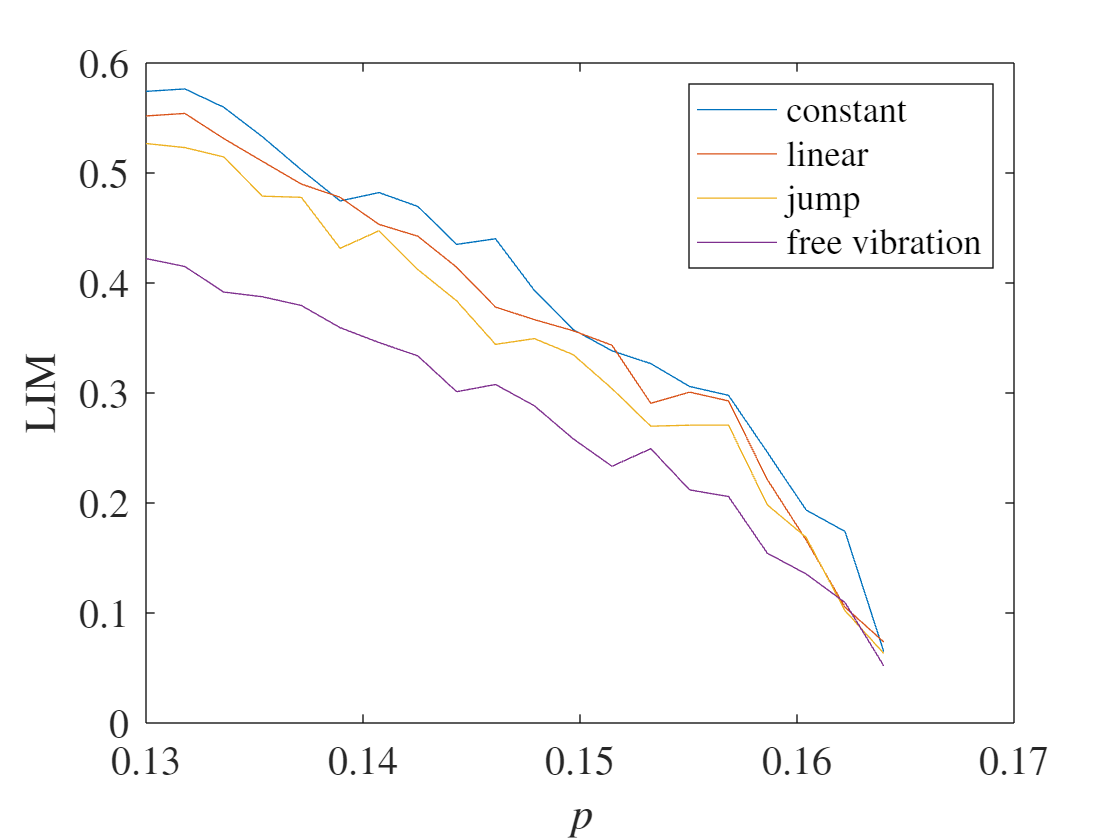


figure;
plot(pvec,R_final0,pvec,R_final1,pvec,R_final2,pvec,R_final3)
xlabel('$p$')
ylabel('LIM')
xlim([0.13,0.17])
set(gca,'FontSize',15)
legend('constant','linear','jump','free vibration')